% EDS images analysis

clc;
clear;
close all;

num = 25;

signal_loc = cell(9, 1);

for f = 65:1:73
    
    folder = [char(f), '/'];
    signal_loc_cod = cell(25, 1);
    
    for ele = 1:1:25
        
        signal_loc_cod_ele = cell(7, 1);
        
        folder_name = [folder, num2str(ele), '/'];
        
        C_image_name = [folder_name, 'C Kα1_2.png'];
        Ca_image_name = [folder_name, 'Ca Kα1.png'];
        Cl_image_name = [folder_name, 'Cl Kα1.png'];
        Mg_image_name = [folder_name, 'Mg Kα1_2.png'];
        Na_image_name = [folder_name, 'Na Kα1_2.png'];
        O_image_name = [folder_name, 'O Kα1.png'];
        S_image_name = [folder_name, 'S Kα1.png'];
        
        C_image = imread(C_image_name);
        Ca_image = imread(Ca_image_name);
        Cl_image = imread(Cl_image_name);
        Mg_image = imread(Mg_image_name);
        Na_image = imread(Na_image_name);
        O_image = imread(O_image_name);
        S_image = imread(S_image_name);
        
        C_image = C_image(:, :, 1) + C_image(:, :, 2) + C_image(:, :, 3);
        Ca_image = Ca_image(:, :, 1) + Ca_image(:, :, 2) + Ca_image(:, :, 3);
        Cl_image = Cl_image(:, :, 1) + Cl_image(:, :, 2) + Cl_image(:, :, 3);
        Mg_image = Mg_image(:, :, 1) + Mg_image(:, :, 2) + Mg_image(:, :, 3);
        Na_image = Na_image(:, :, 1) + Na_image(:, :, 2) + Na_image(:, :, 3);
        O_image = O_image(:, :, 1) + O_image(:, :, 2) + O_image(:, :, 3);
        S_image = S_image(:, :, 1) + S_image(:, :, 2) + S_image(:, :, 3);
        
        dim = size(C_image);
        EDS_collection = zeros(dim(1), dim(2), 7);
        
        EDS_collection(:, :, 1) = C_image;
        EDS_collection(:, :, 2) = Ca_image;
        EDS_collection(:, :, 3) = Cl_image;
        EDS_collection(:, :, 4) = Mg_image;
        EDS_collection(:, :, 5) = Na_image;
        EDS_collection(:, :, 6) = O_image;
        EDS_collection(:, :, 7) = S_image;
        
        for i = 1:1:7
            EDS_collection(:, :, i) = svd_denoise(EDS_collection(:, :, i), 0.37);
            EDS_collection(:, :, i) = medfilt2(EDS_collection(:, :, i), [2, 2]);
            EDS_collection(:, :, i) = imbinarize(EDS_collection(:, :, i), 0.2);
        end
        
        for i = 1:1:7
            [row, col] = find(EDS_collection(:, :, i));
            row = row - 472/2;
            col = col - 630/2;
            dis = row.^2 + col.^2;
            signal_loc_cod_ele{i, 1} = dis;
        end
        
        signal_loc_cod{ele, 1} = signal_loc_cod_ele;
        
    end
    disp(['Processing.....', 'condition:', num2str(f-64)]);
    signal_loc{f-64, 1} = signal_loc_cod;
end

Processing.....condition:1
Processing.....condition:2
Processing.....condition:3
Processing.....condition:4
Processing.....condition:5
Processing.....condition:6
Processing.....condition:7
Processing.....condition:8
Processing.....condition:9


% Under each condition, for 25 images (5 samples with 5 replicates)
% Signal locations of each element were saved
save('signal_location', 'signal_loc', '-v7.3');

signal_location = load('signal_location');
signal_loc = signal_location.signal_loc;

% Under each location, for each water sample, for each element
% signal locations were summed together for 5 replicates
signal_loc_average = cell(9, 1);

for i = 1:1:9
    
    signal_loc_average_con = cell(5, 1);
    
    for j = 0:1:4
        
        signal_average_image = cell(7, 1);
        
        for m = 1:1:5
            
            for k = 1:1:7
                signal_average_image{k, 1} = [signal_average_image{k, 1}; signal_loc{i, 1}{5*j+m, 1}{k, 1}];
            end
            
        end
        
        signal_loc_average_con{j+1, 1} = signal_average_image;
        
    end
    
    signal_loc_average{i, 1} = signal_loc_average_con;
    
end

save('signal_loc_average', 'signal_loc_average', '-v7.3');

signal_loc_average_file = load('signal_loc_average');
signal_loc_average = signal_loc_average_file.signal_loc_average;

% plot differentiation of same element of each pair of water samples (sum of 5
% replicates)
% Under each condition, each element, 5*5 matrix between samples for sum of replicates
matrix = zeros(5*7, 5*9);

for i = 1:1:9
    for j = 1:1:7
        for m = 1:1:5
            for n = 1:1:5
                matrix(m+(j-1)*5, n+(i-1)*5) = ranksum(signal_loc_average{i, 1}{m, 1}{j, 1}, signal_loc_average{i, 1}{n, 1}{j, 1});
                if m == n
                    matrix(m+(j-1)*5, n+(i-1)*5) = 0;
                end
            end
        end
    end
end

close all;
figure1 = figure;
surf(matrix);
colormap(parula);
colorbar;
lim = caxis;
caxis([0, 1]);
caxis([0, 0.005]);
saveas(figure1, 'Mann_test_samples.jpg')
axis off;
save('Mann_elements', 'matrix', '-v7.3');

% plot differentiation of each pair of elements of each water sample (sum of 5
% replicates)
% Under each conditon, each water sample, 7*7 matrix to compare elements
% for sum of replicates
matrix = zeros(5*7, 7*9);

for i = 1:1:9
    for j = 1:1:5
        for m = 1:1:7
            for n = 1:1:7
                matrix(m+(j-1)*7, n+(i-1)*7) = ranksum(signal_loc_average{i, 1}{j, 1}{m, 1}, signal_loc_average{i, 1}{j, 1}{n, 1});
                if m == n
                    matrix(m+(j-1)*7, n+(i-1)*7) = 0;
                end
            end
        end
    end
end

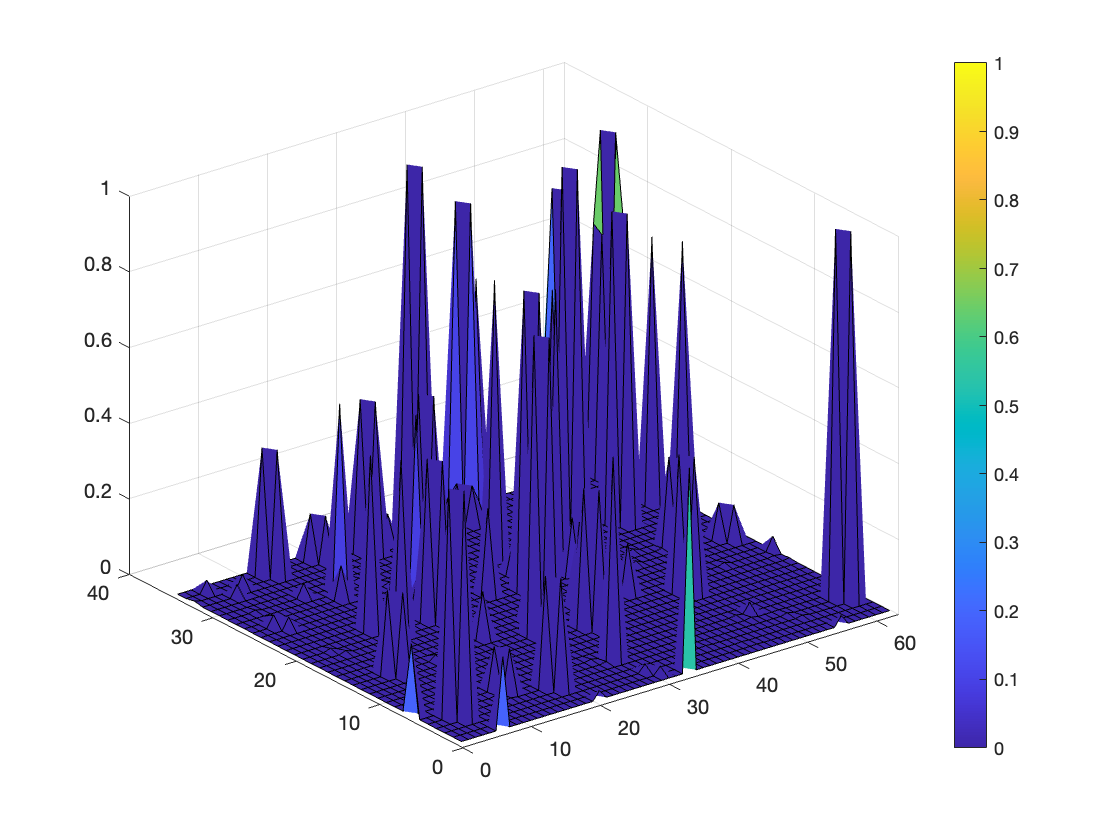

close all;
figure1 = figure;
surf(matrix);
colormap(parula);
colorbar;
lim = caxis;
caxis([0, 1]);
caxis([0, 0.005]);
saveas(figure1, 'Mann_test.jpg')

axis off;
save('Mann_elements', 'matrix', '-v7.3');

element_test_array = zeros(9, 1);

for con = 1:1:9
    for i = 1:1:35
        for j = 1:1:7
            if matrix(i, j+(con-1)*7) <= 0.1
                element_test_array(con, 1) = element_test_array(con, 1) + 1;
            end
        end
    end
end

